## DC motor model

Vn = 6;             % [V]
Te_stall = 16e-3;   % [Nm]
S_no_load = 330;    % [rpm]
N_gear = 100.37;    % [-]
w_no_load = S_no_load*(pi/30)*N_gear; % [rad/s]

La = 1e-4;       % [H]       -> ???
J = 1e-7;        % [kg*m^2]  -> ???

Ke = Vn / w_no_load;
Ra = Vn^2 / (w_no_load*Te_stall);

s = tf('s');
G = (1/Ke) / ((J*La/Ke^2)*s^2 + (J*Ra/Ke^2)*s + 1);
stepplot(G); hold on;

% step response

syms t S Gs Kes Js Las Ras 

Gs = (1/Kes) / ((Js*Las/Kes^2)*S^2 + (Js*Ras/Kes^2)*S + 1)

$$Gs = \frac{1}{\mathrm{Kes}\,\left(\frac{\mathrm{Js}\,\mathrm{Las}\,S^{2}}{{\mathrm{Kes}}^{2}}+\frac{\mathrm{Js}\,\mathrm{Ras}\,S}{{\mathrm{Kes}}^{2}}+1\right)}$$


StepResponse = ilaplace(Gs/S, S, t)

$$StepResponse = \begin{array}{l} \frac{1}{\mathrm{Kes}}-\frac{{\mathrm{e}}^{-\frac{\mathrm{Ras}\,t}{2\,\mathrm{Las}}}\,\left(\cosh\left(\sigma_{1}\right)+\frac{\sqrt{\mathrm{Js}}\,\mathrm{Ras}\,\sinh\left(\sigma_{1}\right)}{2\,\sqrt{\frac{\mathrm{Js}\,{\mathrm{Ras}}^{2}}{4}-{\mathrm{Kes}}^{2}\,\mathrm{Las}}}\right)}{\mathrm{Kes}}\\ \mathrm{where}\\ \sigma_{1}=\frac{t\,\sqrt{\frac{\mathrm{Js}\,{\mathrm{Ras}}^{2}}{4}-{\mathrm{Kes}}^{2}\,\mathrm{Las}}}{\sqrt{\mathrm{Js}}\,\mathrm{Las}} \end{array}$$

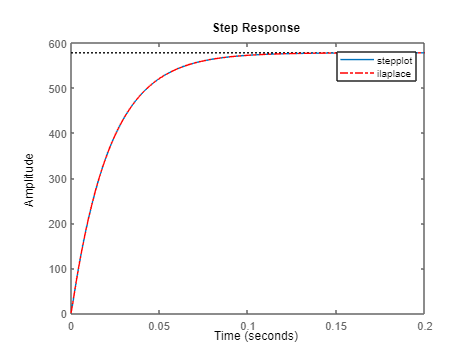


t_vec = 0:1e-3:0.2;
StepResponseVec = double(subs(StepResponse, {Kes, Js, Las, Ras, t}, {Ke, J, La, Ra, t_vec}));
plot(t_vec, StepResponseVec, 'r-.');
legend('stepplot', 'ilaplace');

## Optimization

% optimization function 
% [Te_stall, S_no_load, La, Jw] = findDriveParams(t, w_meas, Vn);

StepResponseMatching = @(x)( mse(StepResponseVec - double(subs(StepResponse, {Kes, Js, Las, Ras, t}, {x(1), x(2), x(3), x(4), t_vec})))  )

StepResponseMatching = function_handle with value:
    @(x)(mse(StepResponseVec-double(subs(StepResponse,{Kes,Js,Las,Ras,t},{x(1),x(2),x(3),x(4),t_vec}))))


lb = [Ke, J, La, Ra]/10;
ub = [Ke, J, La, Ra]*10;
[x,fval,exitflag,output] = fmincon(StepResponseMatching, [Ke, J, La, Ra].*randn(1,4),[],[],[],[],lb,ub)


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x =     0.0017    0.0000    0.0010    6.4868


fval = 9.1300e-07

exitflag = 2

output = struct with fields:
         iterations: 27
          funcCount: 167
    constrviolation: 0
           stepsize: 5.4045e-11
          algorithm: 'interior-point'
      firstorderopt: 7.9921e+06
       cgiterations: 20
            message: '↵Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.↵↵'
       bestfeasible: [1×1 struct]
